To illustrate the functionality we will start by creating a simple 2-link RP planar manipulator.  The first step is to create a robot object that represents the structure and parameters of our robot.

robot = robotics.RigidBodyTree;

A link is defined by a rigid-body object.  Each body is attached to a parent body which is closer to the base of the robot, and has zero or more child body attached to it.

link1 = robotics.RigidBody('link1');

A joint connects two links, RigidBody objects.  The essential characteristics of a joint are the allowable relative motion between the links: rotational (revolute) or translational (prismatic), the axis of that motion, and where the joint attaches to each link.  We can define a revolute joint object

joint1 = robotics.Joint('joint1', 'revolute');

which has a name and a type.  We attach the joint to the distal link

link1.Joint = joint1;

and the attachment point on the distal link is by default the origin of that link frame.  Where the joint attaches to the proximal link is defined with respect to that link's coordinate frame and defined by the fixedTransform property of the joint

joint1.setFixedTransform( transl(5,0,0) );

Finally we connect the links

robot.addBody(link1, 'base');

which specifies the distal link (as an object) and the proximal link by name.  'base' is a predefined name that represents the fixed base of the robot arm, the world coordinate frame effectively.

The Toolbox supports a sophisticated set of transformations from the parent to the child link coordinate frame as shown in Fig ??. The coordinate frame of the child link is given by Tjp^-1 Tj(q) Tcj^-1.  Tj is rotation about, or translation along, the link axis, which is defined as a joint property.  Tjp is set using the setFixedTransform() method of the joint object.  This function can also be used to create a joint axis and set Tjp and Tcj from a Denavit-Hartenberg or modified Denavit-Hartenberg parameter vector by

% joint1.setFixedTransform([a alpha d theta], 'dh')
% joint1.setFixedTransform([a alpha d theta], 'mdh')

We can now add another link to our robot

link2 = robotics.RigidBody('link2');

and this time we will connect it with a prismatic joint that translates in the x-direction with a range of extensions between 0 and 1m

joint2 = robotics.Joint('joint2', 'revolute');

where we have also specified the home position of this joint (which defaults to zero).  We will attach the other side of the joint to link 1 at (1,0,0) in that link's coordinate frame

joint2.setFixedTransform( trvec2tform([1,0,0]) );

then we attach the joint to the link, and the link onto the previous link

link2.Joint = joint2;
robot.addBody(link2, 'link1');

The final step is to add an end-effector.  This is another rigid body

endeffector = robotics.RigidBody('endeffector');

that we attach in a fixed manner to the final link at (0.8, 0.2, 0) in its coordinate frame

endeffector.Joint.setFixedTransform( trvec2tform([0.8,0,0]) );
robot.addBody(endeffector, 'link2');

This approach is very similar to the URDF (universal robot description format) manner of representing a robot.  We can display a summary of the robot we have just built

robot

robot =   RigidBodyTree with properties:

    NumBodies: 3
       Bodies: {[1×1 robotics.RigidBody]  [1×1 robotics.RigidBody]  [1×1 robotics.RigidBody]}
    BodyNames: {'link1'  'link2'  'endeffector'}
     BaseName: 'base'


The robot object contains no joint state at all, that is held in a robot configuration.  This can be created manually or constructed for you by the robot object

q = robot.randomConfiguration;
q = robot.homeConfiguration;
q

q =   1×2 struct array with fields:

    JointName
    JointPosition


The configuration is simply an array of structures, one per joint, and each structure contains the name of the joint (defined at construction time) and its value.

The pose of the end-effector, the forward kinematics is given by

robot.getTransform(q, 'endeffector')

ans =     1.0000         0         0    1.8000
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


We can also obtain relative transformations, for instance

robot.getTransform(q, 'link2', 'endeffector')

ans =     1.0000         0         0    0.8000
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


is the pose of the end-effector with respect to the link 2 frame which is a constant defined above.

We can plot a simple skeleton of the robot in 

ans =   Axes with properties:

             XLim: [-2 2]
             YLim: [-2 2]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


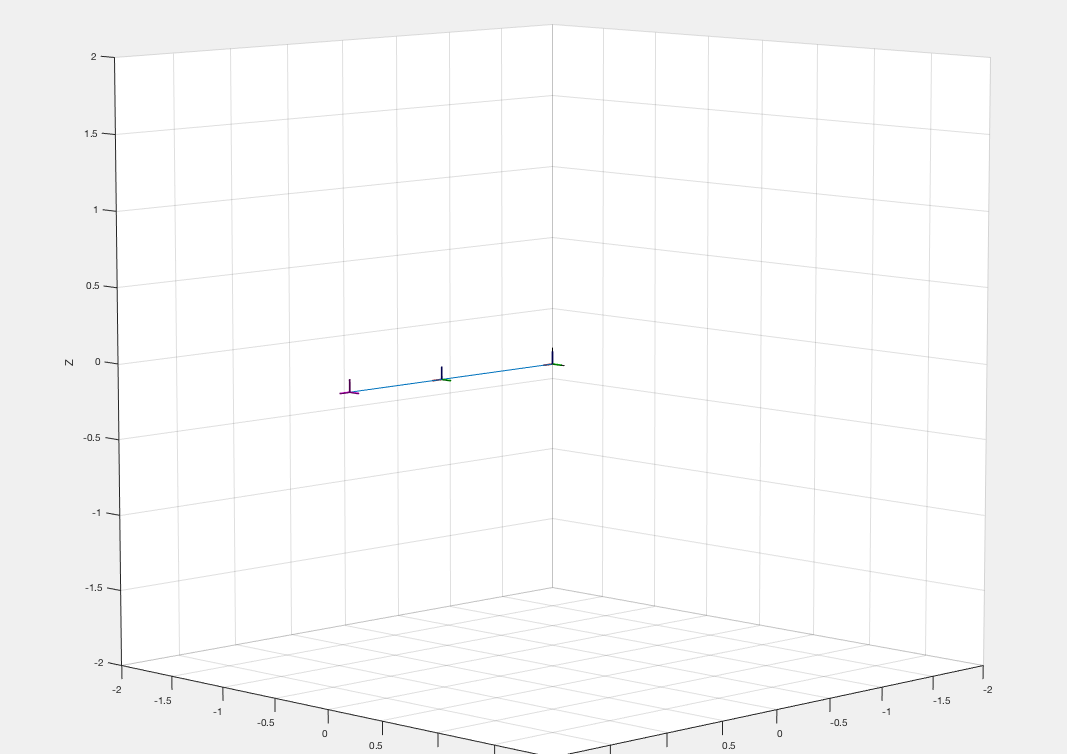

q = robot.homeConfiguration;
robot.show()

where we see the coordinate frames for the base, link 1, link 2 and end-effector -- the first two are superimposed.  We can see more detail by turning on the MATLAB plot browser